# Example 2: Analysis of an .stl file.

First, define the stl file and path for the file you wish to analyse

filepathname = "data/compressor_wheel.stl"; % Full path and name of the .stl file
mytrimesh = trimesh('stl',filepathname); % Create the trimesh object from the .stl file

Calculate properties of the **trimesh** object, define which method of curvature analysis you want to use.

"**none**" will produce the fastest result but have no curvature data - this is the default, and will be used for any other input.

"**trimesh**" uses the trimeshcurvature algorithm based on the paper:  Meyer, M., Desbrun, M., Schröder, P., & Barr, A. H. (2003). Discrete differential-geometry operators for triangulated 2-manifolds. Visualization and mathematics III (pp. 35-57). Springer Berlin Heidelberg. [http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf)

"**patch**" uses the patch curvature function, written by D.Kroon University of Twente (August 2011) . This is based on a fitting a quadratic patch around each local vertex and it's neighbouring vertices. This is typically slower than the trimeshcurvature algorithm.

curvatureMethod = "trimesh"; % Define which method of curvature analysis ("none", "trimesh", "patch")
mytrimesh = mytrimesh.calculateProperties(curvatureMethod);
faceProperties = fieldnames(mytrimesh.Fproperty)

faceProperties = 7×1 cell array
    {'Nx'         }
    {'Ny'         }
    {'Nz'         }
    {'inclination'}
    {'centroid'   }
    {'area'       }
    {'volume'     }


vertexProperties = fieldnames(mytrimesh.Vproperty)

vertexProperties = 14×1 cell array
    {'Nx'         }
    {'Ny'         }
    {'Nz'         }
    {'inclination'}
    {'LPBFQuality'}
    {'Ra'         }
    {'Rz'         }
    {'GC'         }
    {'MC'         }
    {'k1'         }
    {'k2'         }
    {'RMS'        }
    {'ABS'        }
    {'LPBFerror'  }


## Preview the a colored trimesh

Define the **property** you wish to preview. You may use any per-face or per-vertex property within **mytrimesh**, the names of these properties may be found as the fields of **mytrimesh.Fproperty** or **mytrimesh.Vproperty **

You may specify to use "**fancy**" graphics, which will be used be default if nothing is specified.

You may also wish to pass in an **Axis**, which the trimesh will be plotted on - by default a new axis will be created for the figure.

By default, the colorbar automatically scales to capture the 1st-99th percentile data.

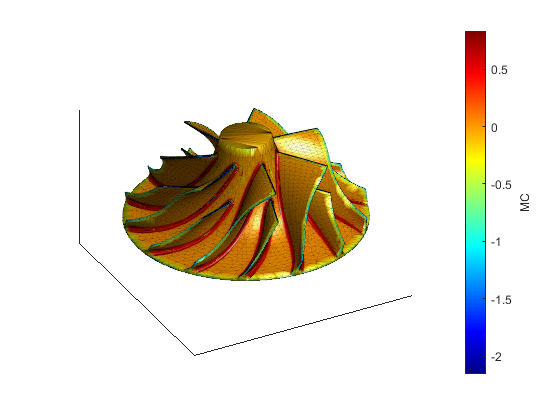

property = 'MC'; % property name must match the string before the space character
fancy = 1; % boolean 1 or 0 to turn fancy graphics on or off.
figure; ax = gca; % gca uses the current axis object
mytrimesh.plotMesh(property,fancy,ax);

## Convert to field data structure

Field based, or implicit data is an alternative way to define geometry. The TPMS designer package includes utilities to convert a **trimesh** object to a **v3field** object which is a voxelised representation of the same geometry.

The user may define a voxel size, smaller numbers will result in higher computational cost, but better resolution.

If you wish to create properties, this can be done by modifying the **v3field.calculateProperties** function and saving the new properties under v3field.properties.

voxelSize = 0.5; %voxelsize in mm
myv3field=mytrimesh.getField(voxelSize);
myv3field=myv3field.calculateProperties % Call the calculate properties method to fill out property data

myv3field =   v3Field with properties:

        name: "data/compressor_wheel.stl"
       lower: [0 0 0]
       upper: [74.9971 74.9946 47.4436]
         res: [150 150 95]
          xq: [1×150 double]
          yq: [1×150 double]
          zq: [1×95 double]
           X: [150×150×95 double]
           Y: [150×150×95 double]
           Z: [150×150×95 double]
           U: [150×150×95 double]
         SDF: [150×150×95 double]
     surface: [150×150×95 double]
       solid: [150×150×95 double]
    property: [1×1 struct]
     zSlices: [1×1 struct]
          CH: []


myv3field.property

ans = struct with fields:
              azimuth: [150×150×95 double]
          inclination: [150×150×95 double]
                   Nx: [150×150×95 double]
                   Ny: [150×150×95 double]
                   Nz: [150×150×95 double]
    manufacturability: [150×150×95 double]


## Preview and visualise field-based properties

Similarly to visualising property of a **trimesh**, the user can visualise **v3field** properties.

You may specify a **sliceHeight** (as a percentage of the total object height) you with to preview the filed property at, this may be added/overlayed on previously made figures. Alternatively set **sliceHeight** = [] to utilise matlab's interactive orthosliceviewer.

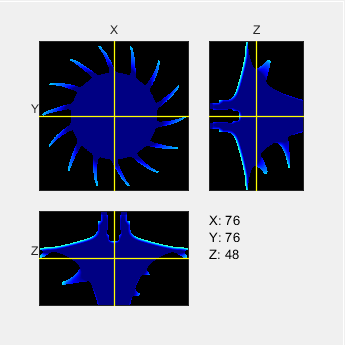

property = "manufacturability";
sliceHeight = []; 
h = myv3field.plotField(property,sliceHeight);

## Further Data Analysis

The distribution of various proeprties can also give inishgts into the performance of a component.

For example, we can look at the probability density distribution of the manufacturability index. The index is defined as -1=empty space, and solid volume ranging from 0 to 1 - where 0 is likely to fail/have problems and 1 being produced without problems.

A design which is more suited to additive manufacturing will have a distribution with a small fraction close to 0 (or volume requiring support structures).

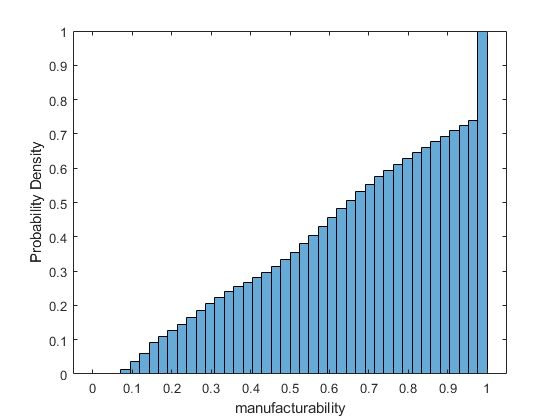

figure
temp = myv3field.property.manufacturability;
temp = temp(myv3field.surface==1);
histogram(temp,'BinLimits',[0 1],'Normalization',"cdf");
%set(gca, 'YScale', 'log'); grid on;
ylabel(gca,'Probability Density'); xlabel(gca,property);

## Using metrics

As the structures investigated are highly complex and are often unwieldy to asses, TPMS Designer utilises a metrics-based approach. This allows a property of a complex design to be approximated with a simplified metric - these are used heavily in **example3_DOE** to compare various properties of TPMS-like structure in a large design of experiments. 

The **metrics** class includes a predefined set of normalised sums, means, maximums or defined percentiles value of various properties, as well as some mechanical metrics for use in comparing cellular structures.

Different metrics may require different properties to be calculated for the field or surface-mesh based representation of an object.

M = metrics;
M = M.fvMetrics(mytrimesh);
M = M.mechanicalMetrics(myv3field)

M =   metrics with properties:

           CPUtime: []
            Nfaces: 31254
            Nnodes: 15629
            volume: 4.0949e+04
    volumeFraction: 0.1738
       surfaceArea: 1.7788e+04
      relativeArea: []
             rmsMC: 0.3712
         thickness: 13.4942
      poreDiameter: 57.8619
           areaVar: 0.0310
          areaMean: 0.1701
           areaStd: 0.1762
    areaBelow30deg: 0.2450
        LpbfRa_Max: 2.2050
       LpbfRa_Mean: 4.4295
    LPBFerror_Mean: 0.0064
     LPBFerror_Max: 113.8000
           elastic: []
           poisson: []
             shear: []
    totalStiffness: []
        zenerRatio: []
         errorFlag: 0
